%% OBJECTIVES
% create visual updates for incoming floats on the ARGOSY notifications
% - Core oceanographic conditions
% - O2, Nitrate, PH, CDOM?
% - NViz and EViz parameters?
% - Highlight recent profiles
% - Time series or profile view?
% - Realtime updates to chem archive, possible an html webpage
% - Create notification that displays current data for new floats (profiles 1 and 6)


warning("off")

%LOAD FLOATS
floatList = readtable("\\atlas\Chem\ARGO_PROCESSING\DATA\CAL\MBARI_float_list.txt");

%Sort any dead floats and those that haven't been deployed yet (Shouldn't be getting new data from those anyways)
floatList = floatList(floatList.tfDead==0 & ~isnat(floatList.x1stDate),:);
floatList = sortrows(floatList(~ismissing(floatList.maxCycleProcDate),:), "maxCycleProcDate", "descend");
floatList = floatList(datenum(floatList.maxCycleProcDate)>=datenum(now-hours(24)),:);

%FOR TESTING ON THE WHOLE FLEET AND NOT PAST 24 HOURS
%floatList = floatList(datenum(floatList.maxCycleProcDate)<=datenum(now),:);

%Create list of float WMO's to call on
% wmoList = floatList.WMO;
% idList = floatList.MBARIID;

% wmoList = [3902557;5907054;5906540];
% idList = {'ua23596';'ua21977';'un1452'};

% wmoList = 5906524;
% idList = {'ua20644'};

wmoList = 5904984;
idList = {'un0569'};


% maxCycleList = floatList.maxCycleProc;

userDir = getenv("USERPROFILE");

% DATA = get_FloatViz_data("\\atlas\chem\ARGO_PROCESSING\DATA\FLOATVIZ\QC\"+wmoList(c)+"QC.txt");
for c = 1:length(wmoList)
    
    disp(wmoList(c))

    plotDir = userDir+"\Documents\plotArchive\"+wmoList(c)
    
    % ===============================================================================================
    disp("Retrieving data")
    if exist("\\atlas\Chem\ARGO_PROCESSING\DATA\FLOATVIZ\QC\"+wmoList(c)+"QC.txt",'file')
        DATA = get_FloatViz_data("\\atlas\Chem\ARGO_PROCESSING\DATA\FLOATVIZ\QC\"+wmoList(c)+"QC.txt");
    else
        disp("No QC data exists for this float")
        continue;
    end

    if ~exist(plotDir,'dir')
        disp('No directory for float previously existed')
        mkdir(plotDir)
    end

    DATA.data(DATA.data==-1e10) = NaN;
    
    DATA.iStn  = find(strcmp('Station', DATA.hdr) == 1);
    DATA.STN = DATA.data(:,DATA.iStn);
    stns = unique(DATA.STN);
    
    DATA.iP    = find(strcmp('Pressure[dbar]', DATA.hdr)  == 1);
    DATA.PRES = DATA.data(:, DATA.iP);
    
    DATA.iT    = find(strcmp('Temperature[°C]', DATA.hdr)  == 1);
    DATA.TEMP = DATA.data(:, DATA.iT);
    
    DATA.iS    = find(strcmp('Salinity[pss]', DATA.hdr)  == 1);
    DATA.SAL = DATA.data(:, DATA.iS);
    
    DATA.iZ    = find(strcmp('Depth[m]', DATA.hdr)  == 1);
    DATA.DEPTH = DATA.data(:, DATA.iZ);
    
    DATA.iO    = find(strcmp('Oxygen[µmol/kg]', DATA.hdr)  == 1);
    DATA.DOX = DATA.data(:, DATA.iO);
    
    DATA.iN    = find(strcmp('Nitrate[µmol/kg]', DATA.hdr) == 1);
    DATA.N= DATA.data(:, DATA.iN);
    
    DATA.iPH   = find(strcmp('pHinsitu[Total]', DATA.hdr)  == 1);
    DATA.PH    = DATA.data(:, DATA.iPH);
    
    DATA.iCHLA  = find(strcmp('Chl_a[mg/m^3]', DATA.hdr)  == 1);
    DATA.CHLA   = DATA.data(:, DATA.iCHLA);
    
    DATA.iLat  = find(strcmp('Lat [°N]', DATA.hdr) == 1);
    DATA.LAT = DATA.data(:, DATA.iLat);
    
    DATA.iLon  = find(strcmp('Lon [°E]', DATA.hdr) == 1);
    DATA.LON = DATA.data(:, DATA.iLon);
    % ===============================================================================================
    disp("Checking for O2 on BSL")
    %CHECK BSL FOR O2 LISTING
    BSL = readtable("\\atlas\Chem\ARGO_PROCESSING\DATA\CAL\bad_sensor_list.TXT");
    BSL = sortrows(BSL,"WMO_","ascend"); %Sort by WMO's in ascending order to match floatsDir
    
    %OXYGEN
    bad_O2_cycles = cellfun(@str2double, regexp(BSL.CYCLES(contains(BSL.SENSOR,"O")&~contains(BSL.SENSOR,"CDOM")&BSL.FLAG==4), ...
        '\d+(?!\-\d+)(?=-)','match'), "UniformOutput",false);
    bad_O2_wmo = BSL(contains(BSL.SENSOR,"O")&~contains(BSL.SENSOR,"CDOM")&BSL.FLAG==4,"WMO_").WMO_;
    
    %Check OXYGEN on the BSL
    BSL_cycle_O2 = cell2mat(bad_O2_cycles(bad_O2_wmo == wmoList(c)));
    badO2Test = ismember(wmoList(c),bad_O2_wmo) & ~isempty(bad_O2_cycles(BSL_cycle_O2));
    if badO2Test
        disp('O2 is indefinitely on BSL, switching to ESPER without O2')
    end
    
    %CHECK FOR STATIONS WITH MISSING O2
    
    %Find all unique stations at over the entire profile
    stns = unique(DATA.STN); 
    
    %Create empty logical array to populate with test results
    noO2logical = logical.empty(length(stns),0);
    
    %Loop through all stations
    for i = 1:length(stns)
    
        %Test if any oxygen is missing from each station and store the test result in the logical array
        noO2logical(i) = any(isnan(DATA.DOX(DATA.STN==stns(i))));
    end
    
    %Retrieve any stations that are missing O2
    noO2stns = stns(noO2logical);
    
    %Apply a blanket test to the entire float
    %If there are missing O2 stations, then it's possible this float is qc'd using ESPER (no O2)
    noO2Test = ~isempty(noO2stns);
    if noO2Test
        disp("Float is missing O2, switching to ESPER without O2")
    end
    %===========================================================================================

    % CALCULATE ESPER PH OR NO3
    Estimates.DesireVar = [3 5];
    Estimates.OutCoords = [DATA.data(:,DATA.iLon), DATA.data(:,DATA.iLat), DATA.data(:,DATA.iZ)]; % lon,lat,Z
    Estimates.PredictorTypes    = [1 2 6]; % PSAL, TEMP, DOXY_ADJ,
    Estimates.Measurements = [DATA.data(:,DATA.iS), DATA.data(:,DATA.iT), DATA.data(:,DATA.iO)];
    Estimates.dvec = datevec(DATA.data(:,1));
    Estimates.dec_yr = Estimates.dvec(:,1) +(Estimates.dvec(:,2)*30)/365 + Estimates.dvec(:,3)/365; % very crude decimal year
    
    if badO2Test | noO2Test
        Equations    = 8; % S, T
        disp("Estimating ESPERMIX without O2")
    else
        Equations    = 7; % S, T, O2
        disp("Estimating ESPERMIX")
    end
    
    %Estimate ESPERMIX with no O2 for the desired variable
    [Estimates,~] = ESPER_Mixed(Estimates.DesireVar, Estimates.OutCoords, Estimates.Measurements,...
                Estimates.PredictorTypes, 'Equations', Equations, 'EstDates', Estimates.dec_yr);
    % ===============================================================================================
    disp("Binning the data")
    %Create a standardized array of depth bins for the mean profiles
    binParams = [8,11:5:100,111:10:400,450:50:1000,1100:100:2000]';
    
    %Create empty arrays that's the same dimension as the pressure bins
    binned_N = NaN(length(binParams),length(stns));
    binned_PH = NaN(length(binParams),length(stns));
    binned_ESPER_N = NaN(length(binParams),length(stns));
    binned_ESPER_PH = NaN(length(binParams),length(stns));
    
    %Sort pressure array by binned pressure
    bins = discretize(DATA.PRES,binParams);
    
    %Calculate the mean difference for every pressure bin
    for i = 1:length(stns)
        for j = 1:length(binParams)
            binned_N(j,i) = mean(DATA.N(DATA.STN==stns(i) & bins==binParams(j)));
            binned_PH(j,i) = mean(DATA.PH(DATA.STN==stns(i) & bins==binParams(j)));
            binned_ESPER_N(j,i) = mean(Estimates.nitrate(DATA.STN==stns(i) & bins==binParams(j)));
            binned_ESPER_PH(j,i) = mean(Estimates.pH(DATA.STN==stns(i) & bins==binParams(j)));
        end
    end
    mean_N = nanmean(binned_N,2);
    mean_PH = nanmean(binned_PH,2);
    mean_ESPER_N = nanmean(binned_ESPER_N,2);
    mean_ESPER_PH = nanmean(binned_ESPER_PH,2);
    % ===============================================================================================
    
    disp("Finding the changepoints")
    %Identify the last cycle where qc was performed by looking at the floatQClist file
    fid = fopen("\\atlas\Chem\ARGO_PROCESSING\DATA\CAL\QC_LISTS\"+wmoList(c)+"_FloatQCList.txt", 'r');
    
    %Create empty string array
    startCycle_ph = {};
    startCycle_nitrate = {};
    
    %Get the first line of the floatQClist file
    next_line = fgetl(fid);
    
    %Iterate through the file until reaching a blank line, indicating
    %the end of the most recent text block
    while ~isempty(next_line)
        next_line = fgetl(fid); %Read the current line
        
        if isempty(next_line)|next_line==-1 %If the current line is empty, end the while loop
            break;
        end
    
        if contains(next_line, 'Nitrate')
            startCycle_nitrate{end+1} = split(next_line,',');
        end
    
        if contains(next_line, 'pH')
            startCycle_ph{end+1} = split(next_line,',');  %Split the string and store it
        end
    end
    
    Nlines = [startCycle_nitrate{1:end}];
    Nchpts = cellfun(@str2double, Nlines(2,:));
    
    PHlines = [startCycle_ph{2:end}];
    PHchpts = cellfun(@str2double, PHlines(2,:));
    % ===============================================================================================
    
    disp("Finding QC depth")
    %FIND THE QC DEPTH FOR PH AND OTHER VARIALBES
    
    %LOAD THE LIST OF PUMP OFFSET FLOATS:
    pH_pumpoffset_980
    
    %If the float is on the pump offset list, subsample to 950m 
    pumpOffset = ismember(wmoList(c),pH_pumpoffset_980_floats);
    
    if pumpOffset
        disp("Pump offset float")
        
        %Subsample the deep data to 950-980m
        DATA.deepPH = DATA.PH(DATA.PRES>=920 & DATA.PRES<=980);
    
        depthRange = [920 980];
     
    %If not, then subsample pH from 1480-1520m
    else 
    
        %Start with initial depth range standard for QC
        depthRange = [1480 1520];
        
        DATA.deepPH = DATA.PH(DATA.PRES>=depthRange(1) & DATA.PRES<=depthRange(2));
        totalStns = unique(DATA.STN);
        deepStns = unique(DATA.STN(DATA.PRES>=depthRange(1) & DATA.PRES<=depthRange(2)));
        shallowFloatTest_ph = 0;
    
        %If there's any missing profiles, progressively increase the depth range by 100
        while all(length(totalStns) ~= length(deepStns))
            
            depthRange = depthRange - 100;
            DATA.deepPH = DATA.PH(DATA.PRES>=depthRange(1) & DATA.PRES<=depthRange(2));
            deepStns = unique(DATA.STN(DATA.PRES>=depthRange(1) & DATA.PRES<=depthRange(2)));
    
            %If no consistent data exists below 500m, consider this a shallow, possible Ross Sea float
            if depthRange(1) <= 500
                disp('No PH data below 500m')
                shallowFloatTest_ph = 1;
                break;
            end
        end
        %While loop ends when a depth with no missing data is reached
        
        disp("Final PH depth range: "+depthRange(1)+"-"+depthRange(2))
        %qcDepth_ph = string(mean(depthRange));
    end
    qcDepth_ph = depthRange;
    qcIDX_ph = DATA.PRES>=qcDepth_ph(1) & DATA.PRES<=qcDepth_ph(2);
    
    %FIND NITRATE QC DEPTH
    
    %Start with initial depth range standard for QC
    depthRange = [1480 1520];
    
    DATA.deepN = DATA.N(DATA.PRES>=depthRange(1) & DATA.PRES<=depthRange(2));
    totalStns = unique(DATA.STN);
    deepStns = unique(DATA.STN(DATA.PRES>=depthRange(1) & DATA.PRES<=depthRange(2)));
    shallowFloatTest_nitrate = 0;
    
    %If there's any missing profiles, progressively increase the depth range by 100
    while all(length(totalStns) ~= length(deepStns))
        
        depthRange = depthRange - 100;
        DATA.deepN = DATA.N(DATA.PRES>=depthRange(1) & DATA.PRES<=depthRange(2));
        deepStns = unique(DATA.STN(DATA.PRES>=depthRange(1) & DATA.PRES<=depthRange(2)));
    
        %If no consistent data exists below 500m, consider this a shallow, possible Ross Sea float or shallow profiling float
        if depthRange(1) <= 500
            disp('No N data below 500m')
            shallowFloatTest_nitrate = 1;
            break;
        end
    end
    %While loop ends when a depth with no missing data is reached
    
    disp("Final N depth range: "+depthRange(1)+"-"+depthRange(2))
    %qcDepth_ph = string(mean(depthRange));
    
    qcDepth = depthRange;
    qcIDX = DATA.PRES>=qcDepth(1) & DATA.PRES<=qcDepth(2);
    % ===============================================================================================
    
    disp("PLOTTING: Fig 1")
    plotpath = plotDir+"\";
    
    fig_prof = figure();
    
    ax = [ ...
        subplot(3,2,1) ...
        subplot(3,2,2) ...
        subplot(3,2,3) ...
        subplot(3,2,4) ...
        subplot(3,2,5) ...
        subplot(3,2,6) ...
        ];
    
    ms = 6;
    lw = .3;
    hold(ax(1), 'on')
    hold(ax(2), 'on')
    hold(ax(3), 'on')
    hold(ax(4), 'on')
    hold(ax(5), 'on')
    hold(ax(6), 'on')
    for i = 1:stns(end)
    
        dat = DATA.data(DATA.STN==i,:);
        pres = dat(:,DATA.iP);
        temp = dat(~isnan(dat(:,DATA.iT)),DATA.iT);
        sal = dat(~isnan(dat(:,DATA.iS)),DATA.iS);
        dox = dat(~isnan(dat(:,DATA.iO)),DATA.iO);
        no3 = dat(~isnan(dat(:,DATA.iN)),DATA.iN);
        ph = dat(~isnan(dat(:,DATA.iPH)),DATA.iPH);
        chla = dat(~isnan(dat(:,DATA.iCHLA)),DATA.iCHLA);
    
        plot(ax(1),temp,pres(~isnan(dat(:,DATA.iT))),'-o','MarkerSize',ms,'LineWidth',lw,'Color','k', ...
            'MarkerEdgeColor','k','MarkerFaceColor','r');
    
        plot(ax(2),no3,pres(~isnan(dat(:,DATA.iN))),'-o','MarkerSize',ms,'LineWidth',lw,'Color','k', ...
            'MarkerEdgeColor','k','MarkerFaceColor',[0.4660 0.6740 0.1880]);
    
        plot(ax(3),sal,pres(~isnan(dat(:,DATA.iS))),'-o','MarkerSize',ms,'LineWidth',lw,'Color','k', ...
            'MarkerEdgeColor','k','MarkerFaceColor',[0 0.4470 0.7410]);
    
        plot(ax(4),ph,pres(~isnan(dat(:,DATA.iPH))),'-o','MarkerSize',ms,'LineWidth',lw,'Color','k', ...
            'MarkerEdgeColor','k','MarkerFaceColor',[0.9290 0.6940 0.1250]);
    
        plot(ax(5),dox,pres(~isnan(dat(:,DATA.iO))),'-o','MarkerSize',ms,'LineWidth',lw,'Color','k', ...
            'MarkerEdgeColor','k','MarkerFaceColor',[0.3010 0.7450 0.9330]);
    
        plot(ax(6),chla,pres(~isnan(dat(:,DATA.iCHLA))),'-o','MarkerSize',ms,'LineWidth',lw,'Color','k', ...
            'MarkerEdgeColor','k','MarkerFaceColor','g');
    end
    
    title(ax(1),wmoList(c) + " (" + idList{c} + ") TEMPERATURE");
    ylabel(ax(1),"Pressure [dBar]");
    xlabel(ax(1),"Temperature [C]");
    
    title(ax(2),wmoList(c) + " (" + idList{c} + ") NITRATE");
    xlabel(ax(2),"Nitrate [µmol/kg]")
    
    title(ax(3),wmoList(c) + " (" + idList{c} + ") SALINITY");
    ylabel(ax(3),"Pressure [dBar]");
    xlabel(ax(3),"Salinity [pss]");
    
    title(ax(4),wmoList(c) + " (" + idList{c} + ") PH");
    xlabel(ax(4),"pH");
    
    title(ax(5),wmoList(c) + " (" + idList{c} + ") OXYGEN");
    xlabel(ax(5),"Oxygen [µmol/kg]");
    ylabel(ax(5),"Pressure [dBar]");
    
    title(ax(6),wmoList(c) + " (" + idList{c} + ") CHLOROPHYL A");
    xlabel(ax(6),"Chlorophyl A [mg/m^3]");
    xlim(ax(6),[-.1 inf]);
    
    ylim(ax,[-100 2000])
    set(ax, 'YDir','reverse')
    
    plotname_prof = 'prof.fig';
    savefig(fig_prof,plotpath+plotname_prof);
    
    close;
    % ===============================================================================================
    disp("PLOTTING: Fig 2")
    fig_prof_recent = figure();
    
    ax = [ ...
        subplot(3,2,1) ...
        subplot(3,2,2) ...
        subplot(3,2,3) ...
        subplot(3,2,4) ...
        subplot(3,2,5) ...
        subplot(3,2,6) ...
        ];
    
    ms = 6;
    lw = .3;
    hold(ax(1), 'on')
    hold(ax(2), 'on')
    hold(ax(3), 'on')
    hold(ax(4), 'on')
    hold(ax(5), 'on')
    hold(ax(6), 'on')
    for i = stns(end-6):stns(end)
    
        dat = DATA.data(DATA.STN==i,:);
        pres = dat(:,DATA.iP);
        temp = dat(~isnan(dat(:,DATA.iT)),DATA.iT);
        sal = dat(~isnan(dat(:,DATA.iS)),DATA.iS);
        dox = dat(~isnan(dat(:,DATA.iO)),DATA.iO);
        no3 = dat(~isnan(dat(:,DATA.iN)),DATA.iN);
        ph = dat(~isnan(dat(:,DATA.iPH)),DATA.iPH);
        chla = dat(~isnan(dat(:,DATA.iCHLA)),DATA.iCHLA);
    
        plot(ax(1),temp,pres(~isnan(dat(:,DATA.iT))),'-o','MarkerSize',ms,'LineWidth',lw,'Color','k', ...
            'MarkerEdgeColor','k','MarkerFaceColor','r');
    
        plot(ax(2),no3,pres(~isnan(dat(:,DATA.iN))),'-o','MarkerSize',ms,'LineWidth',lw,'Color','k', ...
            'MarkerEdgeColor','k','MarkerFaceColor',[0.4660 0.6740 0.1880]);
    
        plot(ax(3),sal,pres(~isnan(dat(:,DATA.iS))),'-o','MarkerSize',ms,'LineWidth',lw,'Color','k', ...
            'MarkerEdgeColor','k','MarkerFaceColor',[0 0.4470 0.7410]);
    
        plot(ax(4),ph,pres(~isnan(dat(:,DATA.iPH))),'-o','MarkerSize',ms,'LineWidth',lw,'Color','k', ...
            'MarkerEdgeColor','k','MarkerFaceColor',[0.9290 0.6940 0.1250]);
    
        plot(ax(5),dox,pres(~isnan(dat(:,DATA.iO))),'-o','MarkerSize',ms,'LineWidth',lw,'Color','k', ...
            'MarkerEdgeColor','k','MarkerFaceColor',[0.3010 0.7450 0.9330]);
    
        plot(ax(6),chla,pres(~isnan(dat(:,DATA.iCHLA))),'-o','MarkerSize',ms,'LineWidth',lw,'Color','k', ...
            'MarkerEdgeColor','k','MarkerFaceColor','g');
    end
    
    title(ax(1),wmoList(c) + " (" + idList{c} + ") TEMPERATURE");
    ylabel(ax(1),"Pressure [dBar]");
    xlabel(ax(1),"Temperature [C]");
    
    title(ax(2),wmoList(c) + " (" + idList{c} + ") NITRATE");
    xlabel(ax(2),"Nitrate [µmol/kg]")
    
    title(ax(3),wmoList(c) + " (" + idList{c} + ") SALINITY");
    ylabel(ax(3),"Pressure [dBar]");
    xlabel(ax(3),"Salinity [pss]");
    
    title(ax(4),wmoList(c) + " (" + idList{c} + ") PH");
    xlabel(ax(4),"pH");
    
    title(ax(5),wmoList(c) + " (" + idList{c} + ") OXYGEN");
    xlabel(ax(5),"Oxygen [µmol/kg]");
    ylabel(ax(5),"Pressure [dBar]");
    
    title(ax(6),wmoList(c) + " (" + idList{c} + ") CHLOROPHYL A");
    xlabel(ax(6),"Chlorophyl A [mg/m^3]");
    xlim(ax(6),[-.1 inf]);
    
    ylim(ax,[-100 2000])
    set(ax, 'YDir','reverse')
    
    plotname_profRecent = 'prof_recent.fig';
    savefig(fig_prof_recent,plotpath+plotname_profRecent);
    
    close;
    % ===============================================================================================
    
    disp("PLOTTING: Fig 3")
    fig_map = figure;
    
    gax = geoaxes; % initiate the geographic axes
    geobasemap(gax, 'landcover'); % several options to choose from
    geoplot(gax, DATA.LAT, DATA.LON,'k.-','MarkerSize',15); % lat, lon
    hold on;
    geoplot(gax,DATA.LAT(1), DATA.LON(1),'g.', 'MarkerSize',20);
    hold on;
    geoplot(gax,DATA.LAT(end), DATA.LON(end),'r.', 'MarkerSize',20);
    
    title(gax,wmoList(c) + "(" + idList{c} + ") MAP");
    legend('', 'First', 'Last', 'Location','bestoutside')
    
    plotname_map = 'map.fig';
    savefig(fig_map,plotpath+plotname_map);
    
    close;
    % ===============================================================================================
    
    disp("PLOTTING: Fig 4")
    fig_refAnom = figure;
    
    ax = [ ...
        subplot(2,2,1) ...
        subplot(2,2,2) ...
        subplot(2,2,3) ...
        subplot(2,2,4) ...
        ];
    
    ms = 30;
    lw = 1;
    
    hold(ax(1), 'on')
    hold(ax(2), 'on')
    
    scatter(ax(1), DATA.STN(qcIDX), DATA.N(qcIDX), ms, "MarkerEdgeColor","k", ...
        "LineWidth", lw, "MarkerFaceColor",[0.3010 0.7450 0.9330]);
    scatter(ax(1), DATA.STN(qcIDX), Estimates.nitrate(qcIDX), ms, "MarkerEdgeColor","k", ...
        "LineWidth", lw, "MarkerFaceColor","red");
    xline(ax(1),Nchpts,'--', 'Color', [0.9290 0.6940 0.1250], 'LineWidth', 2);
    title(ax(1),wmoList(c) + " (" + idList{c} + ") NITRATE @ ("+mean(qcDepth)+"m)");
    ylabel(ax(1),"Nitrate [µmol/kg]");
    xlabel(ax(1),"Station");
    
    scatter(ax(2), DATA.STN(qcIDX_ph), DATA.PH(qcIDX_ph), ms, "MarkerEdgeColor","k", ...
        "LineWidth", lw, "MarkerFaceColor",[0.3010 0.7450 0.9330])
    scatter(ax(2), DATA.STN(qcIDX_ph), Estimates.pH(qcIDX_ph), ms, "MarkerEdgeColor","k", ...
        "LineWidth", lw, "MarkerFaceColor","red");
    xline(ax(2),PHchpts,'--', 'Color', [0.9290 0.6940 0.1250], 'LineWidth', 2);
    title(ax(2),wmoList(c) + " (" + idList{c} + ") PH @ ("+mean(qcDepth_ph)+"m)");
    xlabel(ax(2),"Station");
    ylabel(ax(2),"pH");
    
    if noO2Test | badO2Test
        legend(ax(2),'Float data', 'ESPERmix (no O2)', 'Location','bestoutside')
    else
        legend(ax(2),'Float data', 'ESPERmix', 'Location','bestoutside')
    end
    ax(2).Position(3) = ax(1).Position(3);
    
    scatter(ax(3), DATA.STN(qcIDX), DATA.N(qcIDX)-Estimates.nitrate(qcIDX), ms, "MarkerEdgeColor","k", ...
        "LineWidth", lw, "MarkerFaceColor",[0.4660 0.6 0.2]);
    xline(ax(3),Nchpts,'--', 'Color', [0.9290 0.6940 0.1250], 'LineWidth', 2);
    yline(ax(3),0,'k--', 'LineWidth', 2);
    title(ax(3),"NITRATE reference anomaly");
    ylabel(ax(3),"float-EsperMix [µmol/kg]");
    xlabel(ax(3),"Station");
    
    scatter(ax(4), DATA.STN(qcIDX_ph), DATA.PH(qcIDX_ph)-Estimates.pH(qcIDX_ph), ms, "MarkerEdgeColor","k", ...
        "LineWidth", lw, "MarkerFaceColor",[0.4660 0.6 0.2]);
    xline(ax(4),PHchpts, '--', 'Color', [0.9290 0.6940 0.1250], 'LineWidth', 2);
    yline(ax(4),0,'k--', 'LineWidth', 2);
    title(ax(4),"PH reference anomaly");
    ylabel(ax(4),"float-EsperMix");
    xlabel(ax(4),"Station");
    
    plotname_refAnom = 'refAnom.fig';
    savefig(fig_refAnom,plotpath+plotname_refAnom);
    
    close;
    
    % ===============================================================================================
    
    disp("PLOTTING: Fig 5")
    %Linearly interpolate NaNs for colorplots
    binned_N = fillmissing(binned_N, 'linear', 1);
    binned_ESPER_N = fillmissing(binned_ESPER_N, 'linear', 1);
    binned_PH = fillmissing(binned_PH, 'linear', 1);
    binned_ESPER_PH = fillmissing(binned_ESPER_PH, 'linear', 1);
    
    fig_profileView_N = figure;
    
    ax = [ ...
        subplot(2,2,1) ...
        subplot(2,2,2) ...
        subplot(2,2,3) ...
        subplot(2,2,4)
        ];
    
    
    contourf(ax(1), stns, binParams, binned_N, 'linecolor','none');
    shading(ax(1),'interp')
    title(ax(1),"Nitrate profiles");
    ylabel(ax(1),'Pressure [dbar]');
    xlabel(ax(1),'Station');
    cb = colorbar(ax(1),'EastOutside');
    cb.Label.String = "Nitrate [µmol/kg]";
    cb.Label.FontSize = 10;
    cb.Label.Rotation=-90;
    set(ax(1),'YDir', 'reverse');
    
    ms = 6;
    lw = 1;
    
    hold(ax(2), 'on')
    
    plot(ax(2),mean_N, binParams, '-o','MarkerSize',ms,'LineWidth',lw,'Color','k', ...
            'MarkerEdgeColor','k','MarkerFaceColor',[0.3010 0.7450 0.9330]);
    plot(ax(2),mean_ESPER_N, binParams, '-o','MarkerSize',ms,'LineWidth',lw,'Color','k', ...
            'MarkerEdgeColor','k','MarkerFaceColor','red');
    title(ax(2),"Mean float and ESPERmix profiles");
    xlabel(ax(2),"Nitrate [µmol/kg]");
    set(ax(2),'YDir', 'reverse');
    if noO2Test | badO2Test
        leg = legend(ax(2),'Float data', 'ESPERmix (no O2)', 'Location','bestoutside');
    else
        leg = legend(ax(2),'Float data', 'ESPERmix', 'Location','bestoutside');
    end
    ax(2).Position(3) = ax(1).Position(3);
    ax(2).Position(4) = .31;
    
    contourf(ax(3), stns, binParams, binned_N-binned_ESPER_N, 'linecolor','none');
    shading(ax(3),'interp')
    set(ax(3),'YDir', 'reverse');
    title(ax(3),"Float-ESPERmix profiles");
    ylabel(ax(3),'Pressure [dbar]');
    xlabel(ax(3),'Station');
    cb = colorbar(ax(3),'EastOutside');
    cb.Label.String = "Float-ESPER nitrate";
    cb.Label.FontSize = 10;
    cb.Label.Rotation=-90;
    cmap = cmocean('balance');
    colormap(ax(3),cmap);
    clim(ax(3),[-3 3]);
    
    plot(ax(4),mean_N-mean_ESPER_N, binParams, '-o','MarkerSize',ms,'LineWidth',lw,'Color','k', ...
        'MarkerEdgeColor','k','MarkerFaceColor','k');
    xline(ax(4),0,'--', 'Color', 'red', 'LineWidth', 2);
    title(ax(4),"Mean float-ESPER profile");
    xlabel(ax(4),"float-ESPER");
    ax(4).Position(3) = ax(1).Position(3);
    ax(4).Position(4) = ax(1).Position(4);
    set(ax(4),'YDir', 'reverse');
    
    sgtitle("FLOAT: "+wmoList(c) + " (" + idList{c} + ") NITRATE")
    
    plotname_profileView_N = 'profileView_N.fig';
    savefig(fig_profileView_N,plotpath+plotname_profileView_N);
    
    close;
    % ===============================================================================================
    
    disp("PLOTTING: Fig 6")
    fig_profileView_PH = figure;
    
    ax = [ ...
        subplot(2,2,1) ...
        subplot(2,2,2) ...
        subplot(2,2,3) ...
        subplot(2,2,4)
        ];
    
    
    contourf(ax(1), stns, binParams, binned_PH, 'linecolor','none');
    shading(ax(1),'interp')
    title(ax(1),"pH profiles");
    ylabel(ax(1),'Pressure [dbar]');
    xlabel(ax(1),'Station');
    cb = colorbar(ax(1),'EastOutside');
    cb.Label.String = "pH";
    cb.Label.FontSize = 10;
    cb.Label.Rotation=-90;
    set(ax(1),'YDir', 'reverse');
    
    ms = 6;
    lw = 1;
    
    hold(ax(2), 'on')
    
    plot(ax(2),mean_PH, binParams, '-o','MarkerSize',ms,'LineWidth',lw,'Color','k', ...
            'MarkerEdgeColor','k','MarkerFaceColor',[0.3010 0.7450 0.9330]);
    plot(ax(2),mean_ESPER_PH, binParams, '-o','MarkerSize',ms,'LineWidth',lw,'Color','k', ...
            'MarkerEdgeColor','k','MarkerFaceColor','red');
    title(ax(2),"Mean float and ESPERmix profiles");
    xlabel(ax(2),"PH");
    set(ax(2),'YDir', 'reverse');
    if noO2Test | badO2Test
        leg = legend(ax(2),'Float data', 'ESPERmix (no O2)', 'Location','bestoutside');
    else
        leg = legend(ax(2),'Float data', 'ESPERmix', 'Location','bestoutside');
    end
    ax(2).Position(3) = ax(1).Position(3);
    ax(2).Position(4) = .31;
    
    contourf(ax(3), stns, binParams, binned_PH-binned_ESPER_PH, 'linecolor','none');
    shading(ax(3),'interp')
    set(ax(3),'YDir', 'reverse');
    title(ax(3),"Float-ESPERmix profiles");
    ylabel(ax(3),'Pressure [dbar]');
    xlabel(ax(3),'Station');
    cb = colorbar(ax(3),'EastOutside');
    cb.Label.String = "Float-ESPER pH";
    cb.Label.FontSize = 10;
    cb.Label.Rotation=-90;
    cmap = cmocean('balance');
    colormap(ax(3),cmap);
    clim(ax(3),[-.05 .05]);
    
    plot(ax(4),mean_PH-mean_ESPER_PH, binParams, '-o','MarkerSize',ms,'LineWidth',lw,'Color','k', ...
        'MarkerEdgeColor','k','MarkerFaceColor','k');
    xline(ax(4),0,'--', 'Color', 'red', 'LineWidth', 2);
    title(ax(4),"Mean float-ESPER profile");
    xlabel(ax(4),"float-ESPER");
    ax(4).Position(3) = ax(1).Position(3);
    ax(4).Position(4) = ax(1).Position(4);
    set(ax(4),'YDir', 'reverse');
    
    sgtitle("FLOAT: "+wmoList(c) + " (" + idList{c} + ") PH")
    
    plotname_profileView_PH = 'profileView_PH.fig';
    savefig(fig_profileView_PH,plotpath+plotname_profileView_PH);
    
    close;
end

     5904984



plotDir = "C:\Users\lgrady\Documents\plotArchive\5904984"

Retrieving data


Checking for O2 on BSL


Float is missing O2, switching to ESPER without O2


Estimating ESPERMIX without O2


Estimating anthropogenic carbon for ESPER_NN.
Estimating anthropogenic carbon for ESPER_LIR.


Estimating anthropogenic carbon for ESPER_NN.
Estimating anthropogenic carbon for ESPER_LIR.


Binning the data


Finding the changepoints


Finding QC depth


No PH data below 500m


Final PH depth range: 480-520


No N data below 500m


Final N depth range: 480-520


PLOTTING: Fig 1


PLOTTING: Fig 2


PLOTTING: Fig 3


PLOTTING: Fig 4


PLOTTING: Fig 5


PLOTTING: Fig 6



fig_meanProf = figure;

ax = [ ...
    subplot(2,2,1) ...
    subplot(2,2,2) ...
    subplot(2,2,3) ...
    subplot(2,2,4)
    ];

ms = 6;
lw = 1;

hold(ax(1), 'on')
hold(ax(2), 'on')

plot(ax(1),mean_N, binParams, '-o','MarkerSize',ms,'LineWidth',lw,'Color','k', ...
        'MarkerEdgeColor','k','MarkerFaceColor',[0.3010 0.7450 0.9330]);
plot(ax(1),mean_ESPER_N, binParams, '-o','MarkerSize',ms,'LineWidth',lw,'Color','k', ...
        'MarkerEdgeColor','k','MarkerFaceColor','red');
title(ax(1),wmoList(c) + " (" + idList{c} + ") MEAN NITRATE");
ylabel(ax(1),"PRESSURE [dbar]");
xlabel(ax(1),"NITRATE [µmol/kg]");

plot(ax(2),mean_PH, binParams, '-o','MarkerSize',ms,'LineWidth',lw,'Color','k', ...
        'MarkerEdgeColor','k','MarkerFaceColor',[0.3010 0.7450 0.9330]);
plot(ax(2),mean_ESPER_PH, binParams, '-o','MarkerSize',ms,'LineWidth',lw,'Color','k', ...
        'MarkerEdgeColor','k','MarkerFaceColor','red');
title(ax(2),wmoList(c) + " (" + idList{c} + ") MEAN PH");
ylabel(ax(2),"PRESSURE [dbar]");
xlabel(ax(2),"PH");


if noO2Test | badO2Test
    leg = legend(ax(2),'Float data', 'ESPERmix (no O2)', 'Location','bestoutside')
else
    leg = legend(ax(2),'Float data', 'ESPERmix', 'Location','bestoutside')
end
ax(2).Position(3) = ax(1).Position(3);

plot(ax(3),mean_N-mean_ESPER_N, binParams, '-o','MarkerSize',ms,'LineWidth',lw,'Color','k', ...
    'MarkerEdgeColor','k','MarkerFaceColor','k');
xline(ax(3),0,'--', 'Color', 'red', 'LineWidth', 2);
title(ax(3),"Mean float-ESPER NITRATE");
ylabel(ax(3),"PRESSURE [dbar]");
xlabel(ax(3),"float-ESPER NITRATE");

plot(ax(4),mean_PH-mean_ESPER_PH, binParams, '-o','MarkerSize',ms,'LineWidth',lw,'Color','k', ...
    'MarkerEdgeColor','k','MarkerFaceColor','k');
xline(ax(4),0,'--', 'Color', 'red', 'LineWidth', 2);
title(ax(4),"Mean float-ESPER PH");
ylabel(ax(4),"PRESSURE [dbar]");
xlabel(ax(4),"float-ESPER PH");

set(ax, 'YDir','reverse')

plotname_meanProf = 'meanProf.fig';
savefig(fig_meanProf,[plotpath,plotname_meanProf]);

close;
% ===============================================================================================

leg =   Legend (Float data, ESPERmix) with properties:

         String: {'Float data'  'ESPERmix'}
       Location: 'bestoutside'
    Orientation: 'vertical'
       FontSize: 7.2000
       Position: [0.7224 0.8631 0.1732 0.0631]
          Units: 'normalized'

  Show all properties


cmap =     0.0932    0.1112    0.2615
    0.0970    0.1169    0.2731
    0.1010    0.1224    0.2849
    0.1050    0.1278    0.2969
    0.1090    0.1332    0.3090
    0.1129    0.1385    0.3212
    0.1168    0.1438    0.3335
    0.1205    0.1490    0.3459
    0.1242    0.1542    0.3585
    0.1278    0.1594    0.3712


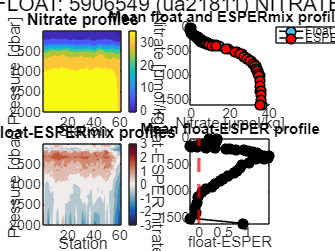

leg =   Legend (Float data, ESPERmix) with properties:

         String: {'Float data'  'ESPERmix'}
       Location: 'bestoutside'
    Orientation: 'vertical'
       FontSize: 7.2000
       Position: [0.7099 0.8631 0.1732 0.0631]
          Units: 'normalized'

  Show all properties


cmap =     0.0932    0.1112    0.2615
    0.0970    0.1169    0.2731
    0.1010    0.1224    0.2849
    0.1050    0.1278    0.2969
    0.1090    0.1332    0.3090
    0.1129    0.1385    0.3212
    0.1168    0.1438    0.3335
    0.1205    0.1490    0.3459
    0.1242    0.1542    0.3585
    0.1278    0.1594    0.3712


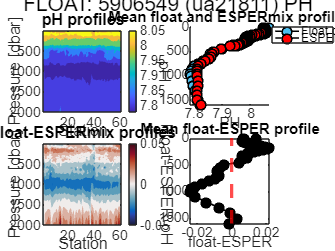

openfig([plotpath,plotname_map]);
openfig([plotpath,plotname_prof]);
openfig([plotpath,plotname_refAnom]);
openfig([plotpath,plotname_meanProf])